# Introduction to MatNWB

## Installing MatNWB

Use the code below within the brackets to install MatNWB from source. MatNWB works by automatically creating API classes based on the schema.

%{
!git clone https://github.com/NeurodataWithoutBorders/matnwb.git
addpath(genpath(pwd));
%}

## Set up the NWB file

An NWB file represents a single session of an experiment. Each file must have a session_description, identifier, and session start time. Create a new [`NWBFile`](https://neurodatawithoutborders.github.io/matnwb/doc/+matnwb/+types/+core/NWBFile.html) object with those and additional metadata using the [`NwbFile`](https://neurodatawithoutborders.github.io/matnwb/doc/NwbFile.html) command. For all MatNWB classes and functions, we use the Matlab method of entering keyword argument pairs, where arguments are entered as name followed by value. Ellipses are used for clarity.

nwb = NwbFile( ...

nwb =   NwbFile with properties:

                                             nwb_version: '2.4.0'
                                             acquisition: [0×1 types.untyped.Set]
                                                analysis: [0×1 types.untyped.Set]
                                        file_create_date: []
                                                 general: [0×1 types.untyped.Set]
                                 general_data_collection: []
                                         general_devices: [0×1 types.untyped.Set]
                          general_experiment_description: []
                                    general_experimenter: 'My Name'
                             general_extracellular_ephys: [0×1 types.untyped.Set]
                  general_extracellular_ephys_electrodes: []
                                     general_institution: 'University of My Institution'
                         

    'session_description', 'mouse in open exploration',...
    'identifier', 'Mouse5_Day3', ...
    'session_start_time', datetime(2018, 4, 25, 2, 30, 3), ...
    'general_experimenter', 'My Name', ... % optional
    'general_session_id', 'session_1234', ... % optional
    'general_institution', 'University of My Institution', ... % optional
    'general_related_publications', 'DOI:10.1016/j.neuron.2016.12.011'); % optional
nwb

## Subject information

You can also provide information about your subject in the NWB file. Create a [`Subject`](https://neurodatawithoutborders.github.io/matnwb/doc/+matnwb/+types/+core/Subject.html) object to store information such as age, species, genotype, sex, and a freeform description. Then set `nwb.general_subject` to the [`Subject`](https://neurodatawithoutborders.github.io/matnwb/doc/+matnwb/+types/+core/Subject.html) object.

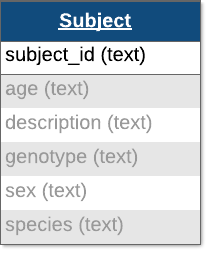

Each of these fields is free-form, so any values will be valid, but here are our recommendations:

- For `age`, we recommend using the [ISO 8601 Duration format](https://en.wikipedia.org/wiki/ISO_8601#Durations)

- For `species`, we recommend using the formal latin binomal name (e.g. mouse -> *Mus musculus*, human -> *Homo sapiens*)

- For `sex`, we recommend using F (female), M (male), U (unknown), and O (other)

subject = matnwb.types.core.Subject( ...
    'subject_id', '001', ...
    'age', 'P90D', ...

subject =   Subject with properties:

              age: 'P90D'
    date_of_birth: []
      description: 'mouse 5'
         genotype: []
              sex: 'M'
          species: 'Mus musculus'
           strain: []
       subject_id: '001'
           weight: []


    'description', 'mouse 5', ...
    'species', 'Mus musculus', ...
    'sex', 'M' ...
);
nwb.general_subject = subject;

subject

Note: the DANDI archive requires all NWB files to have a subject object with subject_id specified, and strongly encourages specifying the other fields.

## Behavior

### SpatialSeries and Position

Many types of data have special data types in NWB. To store the spatial position of a subject, we will use the [`SpatialSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+matnwb/+types/+core/SpatialSeries.html) and [`Position`](https://neurodatawithoutborders.github.io/matnwb/doc/+matnwb/+types/+core/Position.html) classes. 

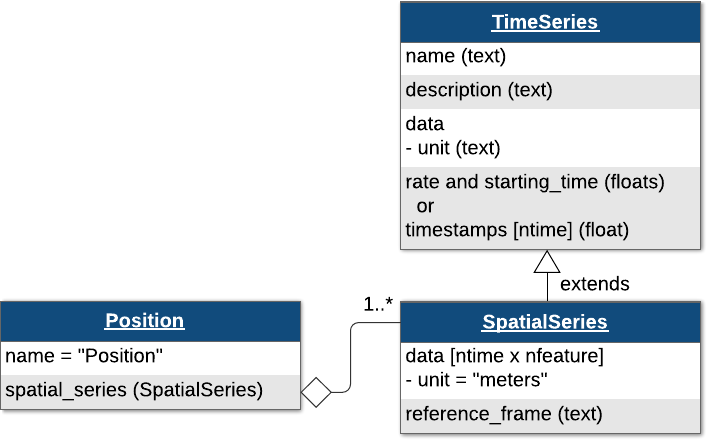 

Note: These diagrams follow a standard convention called "UML class diagram" to express the object-oriented relationships between NWB classes. For our purposes, all you need to know is that an open triangle means "extends" and an open diamond means "is contained within." Learn more about class diagrams on [the wikipedia page](https://en.wikipedia.org/wiki/Class_diagram).

[`SpatialSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+matnwb/+types/+core/SpatialSeries.html) is a subclass of [`TimeSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+matnwb/+types/+core/TimeSeries.html), a common base class for measurements sampled over time, and provides fields for data and time (regularly or irregularly sampled). Here, we put a [`SpatialSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+matnwb/+types/+core/SpatialSeries.html) object called `'SpatialSeries'` in a [`Position`](https://neurodatawithoutborders.github.io/matnwb/doc/+matnwb/+types/+core/Position.html) object. 

% create SpatialSeries object
spatial_series_ts = matnwb.types.core.SpatialSeries( ...
    'data', [linspace(0,10,100); linspace(0,8,100)], ...
    'reference_frame', '(0,0) is bottom left corner', ...
    'timestamps', linspace(0, 100)/200 ...
);

% create Position object and add SpatialSeries
Position = matnwb.types.core.Position('SpatialSeries', spatial_series_ts);

% create processing module
behavior_mod = matnwb.types.core.ProcessingModule('description',  'contains behavioral data');

% add the Position object (that holds the SpatialSeries object)
behavior_mod.nwbdatainterface.set('Position', Position);

NWB differentiates between raw, *acquired *data, which should never change, and *processed *data, which are the results of preprocessing algorithms and could change. Let's assume that the animal's position was computed from a video tracking algorithm, so it would be classified as processed data. Since processed data can be very diverse, NWB allows us to create processing modules, which are like folders, to store related processed data or data that comes from a single algorithm. 

Create a processing module called "behavior" for storing behavioral data in the [`NWBFile`](https://neurodatawithoutborders.github.io/matnwb/doc/+matnwb/+types/+core/NWBFile.html) and add the [`Position`](https://neurodatawithoutborders.github.io/matnwb/doc/+matnwb/+types/+core/Position.html) object to the module.

% create processing module
behavior_mod = matnwb.types.core.ProcessingModule('description',  'contains behavioral data');

% add the Position object (that holds the SpatialSeries object) to the
% module and name the Position object "Position"
behavior_mod.nwbdatainterface.set('Position', Position);

% add the processing module to the NWBFile object, and name the processing module "behavior"
nwb.processing.set('behavior', behavior_mod);

### Trials

Trials are stored in a [`TimeIntervals`](https://neurodatawithoutborders.github.io/matnwb/doc/+matnwb/+types/+core/TimeIntervals.html) object which is a subclass of [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+matnwb/+types/+hdmf_common/DynamicTable.html). [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+matnwb/+types/+hdmf_common/DynamicTable.html) objects are used to store tabular metadata throughout NWB, including for trials, electrodes, and sorted units. They offer flexibility for tabular data by allowing required columns, optional columns, and custom columns.

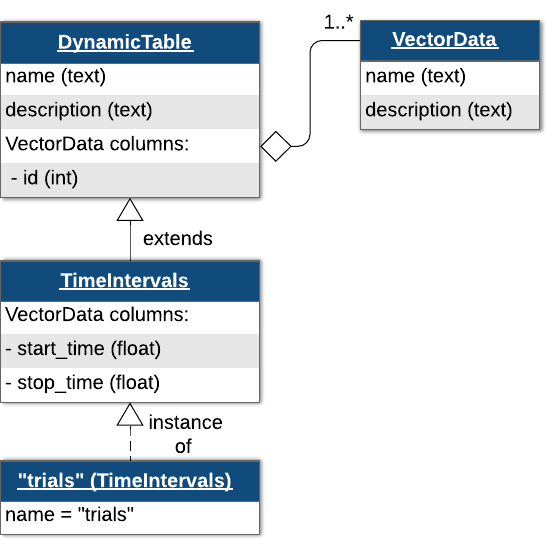

The trials [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+matnwb/+types/+hdmf_common/DynamicTable.html) can be thought of as a table with this structure:

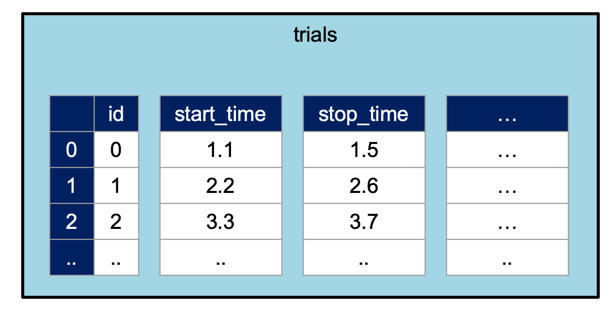

Trials are stored in a [`TimeIntervals`](https://neurodatawithoutborders.github.io/matnwb/doc/+matnwb/+types/+core/TimeIntervals.html) object which subclasses [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+matnwb/+types/+hdmf_common/DynamicTable.html). Here, we are adding `'correct'`, which will be a logical array.

trials = matnwb.types.core.TimeIntervals( ...
    'colnames', {'start_time', 'stop_time', 'correct'}, ...
    'description', 'trial data and properties', ...
    'id', matnwb.types.hdmf_common.ElementIdentifiers('data', 0:2), ...
    'start_time', matnwb.types.hdmf_common.VectorData( ...
        'data', [0.1, 1.5, 2.5], ...
   	    'description','start time of trial in seconds' ...
    ), ...
    'stop_time', matnwb.types.hdmf_common.VectorData( ...
        'data', [1.0, 2.0, 3.0], ...
   	    'description','end of each trial in seconds' ...
    ), ...
    'correct', matnwb.types.hdmf_common.VectorData( ...
        'data', [false, true, false], ...
   	    'description', 'whether the trial was correct') ...
    );
nwb.intervals_trials = trials;

## Write

Now, to write the NWB file that we have built so far:

nwbExport(nwb, 'intro_tutorial.nwb')

We can use the [HDFView](https://www.hdfgroup.org/downloads/hdfview/) application to inspect the resulting NWB file.

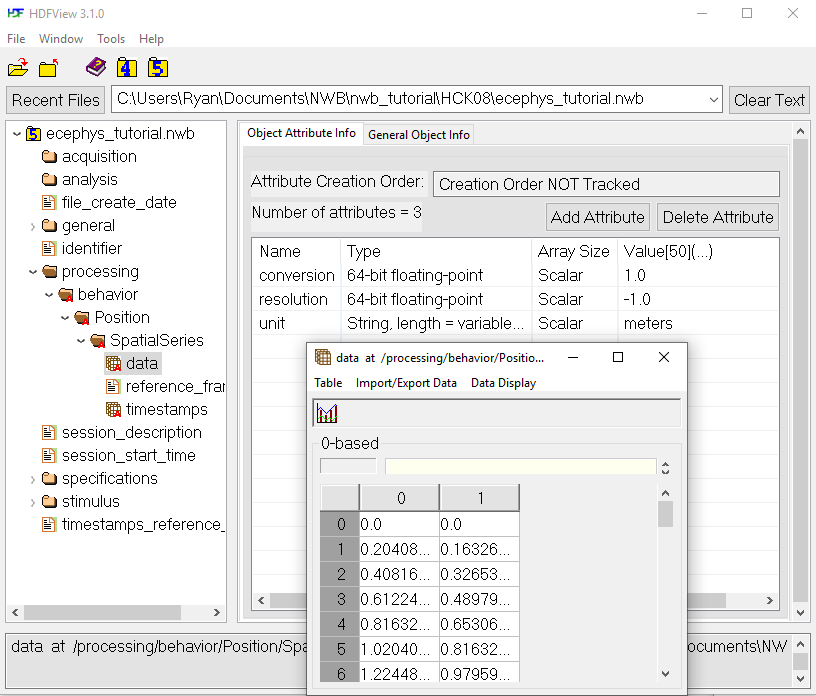

## Read

We can then read the file back in using MatNWB and inspect its contents. 

read_nwbfile = nwbRead('intro_tutorial.nwb', 'ignorecache')

read_nwbfile =   NwbFile with properties:

                                             nwb_version: '2.4.0'
                                             acquisition: [0×1 types.untyped.Set]
                                                analysis: [0×1 types.untyped.Set]
                                        file_create_date: [1×1 types.untyped.DataStub]
                                                 general: [0×1 types.untyped.Set]
                                 general_data_collection: []
                                         general_devices: [0×1 types.untyped.Set]
                          general_experiment_description: []
                                    general_experimenter: [1×1 types.untyped.DataStub]
                             general_extracellular_ephys: [0×1 types.untyped.Set]
                  general_extracellular_ephys_electrodes: []
                                     general_institution: 'U

We can print the [`SpatialSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+matnwb/+types/+core/SpatialSeries.html) data traversing the hierarchy of objects. The processing module called `'behavior'` contains our [`Position`](https://neurodatawithoutborders.github.io/matnwb/doc/+matnwb/+types/+core/Position.html) object named `'Position'`. The [`Position`](https://neurodatawithoutborders.github.io/matnwb/doc/+matnwb/+types/+core/Position.html) object contains our [`SpatialSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+matnwb/+types/+core/SpatialSeries.html) object named `'SpatialSeries'`.

read_spatial_series = read_nwbfile.processing.get('behavior'). ...
    nwbdatainterface.get('Position').spatialseries.get('SpatialSeries')

read_spatial_series =   SpatialSeries with properties:

        reference_frame: '(0,0) is bottom left corner'
     starting_time_unit: 'seconds'
    timestamps_interval: 1
        timestamps_unit: 'seconds'
               comments: 'no comments'
                control: []
    control_description: []
                   data: [1×1 types.untyped.DataStub]
        data_continuity: []
        data_conversion: 1
        data_resolution: -1
              data_unit: 'meters'
            description: 'no description'
          starting_time: []
     starting_time_rate: []
             timestamps: [1×1 types.untyped.DataStub]


### Reading data

Counter to normal MATLAB workflow, data arrays are read passively from the file. Calling `read_spatial_series.data` does not read the data values, but presents a `DataStub` object that can be indexed to read data. 

read_spatial_series.data

ans =   DataStub with properties:

    filename: 'intro_tutorial.nwb'
        path: '/processing/behavior/Position/SpatialSeries/data'
        dims: [2 100]
       ndims: 2


This allows you to conveniently work with datasets that are too large to fit in RAM all at once. Access all the data in the matrix using the `load` method with no arguments. 

read_spatial_series.data.load

ans =          0    0.1010    0.2020    0.3030    0.4040    0.5051    0.6061    0.7071    0.8081    0.9091    1.0101    1.1111    1.2121    1.3131    1.4141    1.5152    1.6162    1.7172    1.8182    1.9192    2.0202    2.1212    2.2222    2.3232    2.4242    2.5253    2.6263    2.7273    2.8283    2.9293    3.0303    3.1313    3.2323    3.3333    3.4343    3.5354    3.6364    3.7374    3.8384    3.9394    4.0404    4.1414    4.2424    4.3434    4.4444    4.5455    4.6465    4.7475    4.8485    4.9495
         0    0.0808    0.1616    0.2424    0.3232    0.4040    0.4848    0.5657    0.6465    0.7273    0.8081    0.8889    0.9697    1.0505    1.1313    1.2121    1.2929    1.3737    1.4545    1.5354    1.6162    1.6970    1.7778    1.8586    1.9394    2.0202    2.1010    2.1818    2.2626    2.3434    2.4242    2.5051    2.5859    2.6667    2.7475    2.8283    2.9091    2.9899    3.0707    3.1515    3.2323    3.3131    3.3939    3.4747    3.5556    3.6364    3.7172    3.7980    3.8788   

If you only need a section of the data, you can read only that section by indexing the `DataStub` object like a normal array in MATLAB. This will just read the selected region from disk into RAM. This technique is particularly useful if you are dealing with a large dataset that is too big to fit entirely into your available RAM.

read_spatial_series.data(:, 1:10)

ans =          0    0.1010    0.2020    0.3030    0.4040    0.5051    0.6061    0.7071    0.8081    0.9091
         0    0.0808    0.1616    0.2424    0.3232    0.4040    0.4848    0.5657    0.6465    0.7273


## Next steps

This concludes the introductory tutorial. Please proceed to one of the specialized tutorials, which are designed to follow this one.

- [Extracellular electrophysiology](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/ecephys.html)

- [Intracellular electrophysiology](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/icephys.html)

- [Optical physiology](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/ophys.html)

See the [API documentation](https://neurodatawithoutborders.github.io/matnwb/doc/index.html) to learn what data types are available.